syms x epsilon real
eps = 0.1;
dl = -0.5; dr = 0.5;
kl = 1.8; kr = 2.3;
Sl = -9; Sr = 12;
u = -15 : 0.01 : 15;

softplus(x, epsilon) = epsilon * log(1 + exp(x / epsilon));
disp(softplus);

$$\epsilon \,\log\left({\mathrm{e}}^{x/\epsilon }+1\right)$$

% plot(u, softplus(u, eps));

softplus_r(x, epsilon) = softplus(x - dr, epsilon);
softplus_l(x, epsilon) = softplus(dl - x, epsilon);
% plot(u, [softplus_l(u, eps); softplus_r(u, eps)]);

w_soft(x, epsilon) = kr * softplus_r(x, epsilon) - kl * softplus_l(x, epsilon);
disp(w_soft);

$$\frac{23\,\epsilon \,\log\left({\mathrm{e}}^{\frac{x-\frac{1}{2}}{\epsilon }}+1\right)}{10}-\frac{9\,\epsilon \,\log\left({\mathrm{e}}^{-\frac{x+\frac{1}{2}}{\epsilon }}+1\right)}{5}$$


% epsilon_ls = [0.01 0.1 1];
% w_soft_ls = zeros(numel(epsilon_ls), numel(u));
% labels = strings(1, numel(epsilon_ls));
% for i = 1:numel(epsilon_ls)
%     w_soft_ls(i, :) = w_soft(u, epsilon_ls(i));
%     labels(i) = sprintf("\\epsilon = %.4f", epsilon_ls(i));
% end
% plot(u, w_soft_ls);
% legend(labels);

v(x) = piecewise(x >= 0, Sr * tanh(w_soft(x, eps) / Sr), ...
                 x < 0, Sl * tanh(w_soft(x, eps) / Sl));
disp(v);

$$\left\{ \begin{array}{cl} -12\,\tanh\left(\frac{3\,\log\left({\mathrm{e}}^{-10\,x-5}+1\right)}{200}-\frac{23\,\log\left({\mathrm{e}}^{10\,x-5}+1\right)}{1200}\right) & \text{ if }0\leq x\\ -9\,\tanh\left(\frac{\log\left({\mathrm{e}}^{-10\,x-5}+1\right)}{50}-\frac{23\,\log\left({\mathrm{e}}^{10\,x-5}+1\right)}{900}\right) & \text{ if }x<0 \end{array}\right.$$

var = vpa(v)

$$var(x) = \left\{ \begin{array}{cl} -12.0\,\tanh\left(0.015\,\log\left({\mathrm{e}}^{-10.0\,x-5.0}+1.0\right)-0.019166666666666666666666666666667\,\log\left({\mathrm{e}}^{10.0\,x-5.0}+1.0\right)\right) & \text{ if }0\leq x\\ -9.0\,\tanh\left(0.02\,\log\left({\mathrm{e}}^{-10.0\,x-5.0}+1.0\right)-0.025555555555555555555555555555556\,\log\left({\mathrm{e}}^{10.0\,x-5.0}+1.0\right)\right) & \text{ if }x<0 \end{array}\right.$$

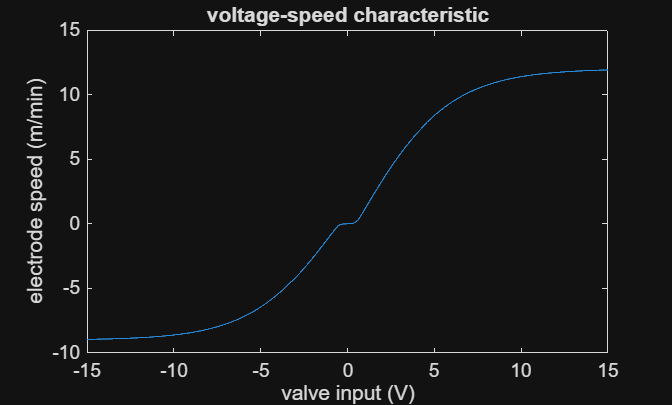

plot(u, v(u));
xlabel("valve input (V)");
ylabel("electrode speed (m/min)");
title("voltage-speed characteristic");